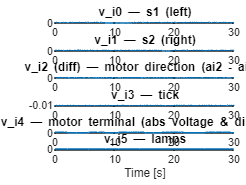

% NI DAQ (Data Acquisition Toolbox) — 1 kHz, 10k samples
% Reads analog voltages v_i0…v_i5. v_i2 is measured differentially as (ai2 - ai10).
% All others are RSE (in DAQ terminology: TerminalConfig = "SingleEnded").

dev = "Dev1";           % adjust if your NI device has a different ID (see daqlist)
Fs  = 1000;             % sample rate [Hz]
N   = 30000;            % number of samples (scans) == 10 s at 1 kHz

dq = daq("ni");
dq.Rate = Fs;

% Helper to add one SE (RSE) voltage channel with a custom Name and range
addSE = @(chan,name) ( ...
    set( addinput(dq, dev, chan, "Voltage"), ...
         "Name", name, "TerminalConfig", "SingleEnded", "Range", [-10 10]) );

% Channels:
% v_i0 - s1 (RSE)
addSE("ai0","v_i0"); 
% v_i1 - s2 (RSE)
addSE("ai1","v_i1");
% v_i2 (diff) - motor direction  -> acquire ai2 and reference ai10, compute v_i2 = ai2 - ai10
addSE("ai2","ai2_raw");
addSE("ai10","v_10");  % explicit reference for the software-differential
% v_i3 - tick (RSE)
addSE("ai3","v_i3");
% v_i4 - absolute motor voltage & direction (other terminal) (RSE)
addSE("ai4","v_i4");
% v_i5 - two lamps (RSE)
addSE("ai5","v_i5");

% Acquire
T = seconds(N/Fs);
data = read(dq, T, "OutputFormat","timetable");   % timetable with channel Names as variables

% Construct the differential signal v_i2 = ai2_raw - v_10
data.v_i2 = data.ai2_raw - data.v_10;

% Optional: keep only required outputs in a new timetable (preserve time)
out = timetable(data.Time, data.v_i0, data.v_i1, data.v_i2, data.v_i3, data.v_i4, data.v_i5, ...
                'VariableNames', {'v_i0','v_i1','v_i2','v_i3','v_i4','v_i5'});

% Plot — separate axes for each signal
t = seconds(out.Time - out.Time(1));  % start at t=0 s
tl = tiledlayout(6,1,'TileSpacing','compact','Padding','compact');
labels = { ...
    'v\_i0 — s1 (left)', ...
    'v\_i1 — s2 (right)', ...
    'v\_i2 (diff) — motor direction (ai2 - ai10)', ...
    'v\_i3 — tick', ...
    'v\_i4 — motor terminal (abs voltage & direction)', ...
    'v\_i5 — lamps'};

for k = 1:6
    ax = nexttile;
    plot(ax, t, out{:,k});
    grid(ax, 'on');
    ylabel(ax, 'V');
    title(ax, labels{k});
end
xlabel(nexttile(6), 'Time [s]');


% Notes:
% - "SingleEnded" here corresponds to RSE (referenced single-ended to device ground).
% - If your NI device supports true hardware differential with a selectable negative input,
%   you can switch ai2 to Differential: ch = addinput(...,"ai2","Voltage"); ch.TerminalConfig="Differential";
%   However, pairing ai2 with ai10 as the specific negative input is hardware-dependent, so the
%   software differential (ai2_raw - v_10) above guarantees ai10 as reference.
